# `isiceshelf` documentation

The `isiceshelf` function returns logical true for all ice shelf locations according to MEaSURES Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. 

The Antarctic Boundaries dataset is described on the NSIDC site [here](http://nsidc.org/data/NSIDC-0709). An overview of the tools in this AMT plugin can be found [here](Antbounds_Contents.html).

## Syntax

## Description

`tf = isiceshelf(lati,loni)` returns true for all geo locations `(lati,loni)` identified as ice shelf in the Mask_Antactica_v2.tif (sic) dataset. 

`tf = isiceshelf(xi,yi)` returns true for all locations identified as ice shelf in Mask_Antactica_v2.tif (sic), where input coordinates are automatically determined to be polar stereographic (true lat 71 S) meters if their values exceed the normal lat,lon range. 

`tf = isiceshelf(...,IceShelfName)` only returns true for points corresponding to the given ice shelf. This method is computationally slower becuase it uses `inpolygon` (rather than `interp2` of Mask_Antactica_v2.tif) to find points within an ice shelf boundary. The names of all 181 ice shelves are available in the [`antbounds_data`](antbounds_data_documentation.html) documentation. 

`tf = isiceshelf(...,'RumplesTrue')` lets ice rumples within an ice shelf be true. By default, an pinning points or ice rumples are grounded and are therefore not considered part of the ice shelf, but with the `'RumplesTrue'` option, pinning points and rumples such as those in Pine Island and Totten ice shelves are true. 

## Example 1: Mask a gravity dataset:

This example uses a [Gravity Plugin for AMT](https://www.mathworks.com/matlabcentral/fileexchange/54915) to load some example data, but I'll show you how you can follow along without loading that dataset. Whether you have the gravity plugin or not, begin by creating a 300 km wide grid centered on PIG, at 0.25 km resolution:

[lat,lon] = psgrid('pine island glacier',300,0.25);

If you have the gravity plugin, interpolate gravity values to the grid like this: 

FA = gravity_interp(lat,lon,'free air');

If you don't have the gravity plugin you can simply use random data like this: 

Use `isiceshelf` to find out which parts of the dataset are ice shelf: 

shelf = isiceshelf(lat,lon);

Mask-out all non-grounded ice (use the tilde for NOT) by setting it to NaN: 

FA(~shelf) = NaN;

Plot the gravity data corresponding to ice shelf locations: 

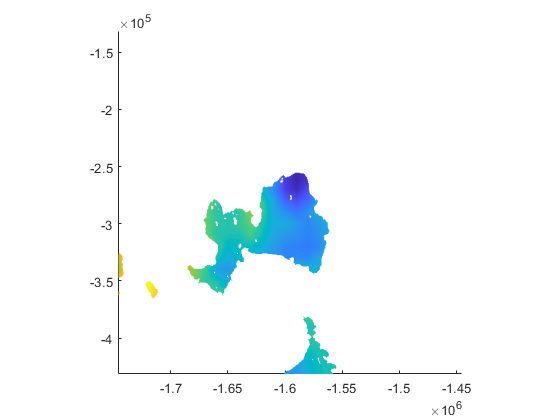

pcolorps(lat,lon,FA)
axis tight

For context, overlay a red grounding line and a black coastline and an inset map: 

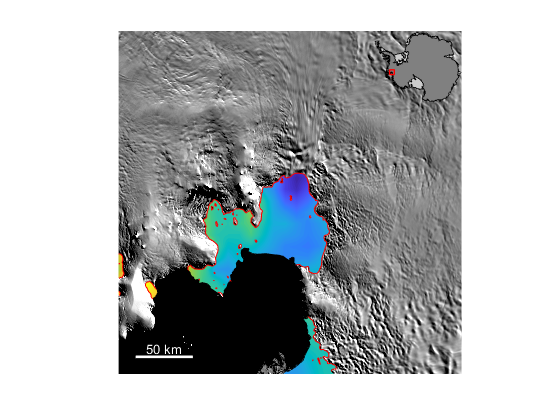

antbounds('gl','red') 
antbounds('coast','black')

mapzoomps('ne','frame','off') 
modismoaps % underlay a MODIS Mosaic of Antarctica image
scalebarps('color','w') 
axis off % removes x,y values from axes

## Example 2: A single ice shelf

If you only want to consider a single ice shelf, just name your favorite ice shelf, and the `isiceshelf` function will return `true` **only** for locations in that ice shelf. Following the example above, if you are only interested in Pine Island Glacier's ice shelf, get a mask like this: 

PIG = isiceshelf(lat,lon,'pine island');

If you want to prevent ice rumples from showing up as holes in your data, use the `'RumplesTrue'` option:

PIG2 = isiceshelf(lat,lon,'pine island','RumplesTrue');

Then it's a matter of masking by setting non-pig values to NaN, just as in the first example: 

FA = gravity_interp(lat,lon,'free air');
FA(~PIG) = nan; 
FA2 = gravity_interp(lat,lon,'free air');
FA2(~PIG2) = nan;

Then plot: 

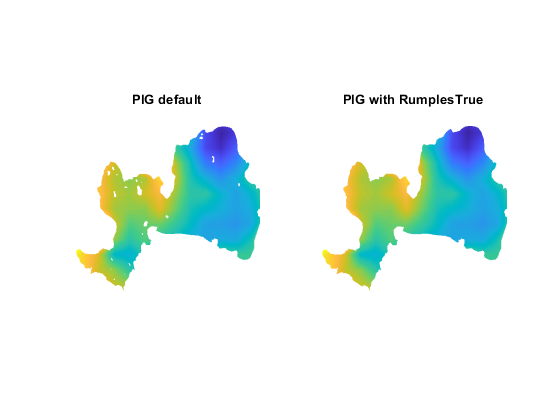

figure
subplot(1,2,1) 
pcolorps(lat,lon,FA) 
axis([-1687203 -1564208 -367471 -244477])
title 'PIG default'
axis off

subplot(1,2,2) 
pcolorps(lat,lon,FA2) 
axis([-1687203 -1564208 -367471 -244477])
title 'PIG with RumplesTrue'
axis off

## Citing this dataset

If you use this dataset, please cite the following: 

- **The dataset:** Mouginot, J., B. Scheuchl, and E. Rignot. 2017. MEaSUREs Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. [Indicate subset used]. Boulder, Colorado USA. NASA National Snow and Ice Data Center Distributed Active Archive Center. [http://dx.doi.org/10.5067/AXE4121732AD](http://dx.doi.org/10.5067/AXE4121732AD). 

- **Literature citation:** Rignot, E., S. S. Jacobs, J. Mouginot, and B. Scheuchl. 2013. Ice-shelf melting around Antarctica, Science. 341. 266-270. [http://dx.doi.org/10.1126/science.1235798](http://dx.doi.org/10.1126/science.1235798). 

- **Antarctic Mapping Tools:** Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function and supporting documentation were written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), November 2016. Updated May 2017 and May 2018. 